x=0:3

x =      0     1     2     3


y=[-5, -6, -1, 16]

y =     -5    -6    -1    16


u = -.25:.01:3.25

u =    -0.2500   -0.2400   -0.2300   -0.2200   -0.2100   -0.2000   -0.1900   -0.1800   -0.1700   -0.1600   -0.1500   -0.1400   -0.1300   -0.1200   -0.1100   -0.1000   -0.0900   -0.0800   -0.0700   -0.0600   -0.0500   -0.0400   -0.0300   -0.0200   -0.0100         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400


v1=lagrange_polyinterp1(x,y,u)

v1 =    -4.5156
   -4.5338
   -4.5522
   -4.5706
   -4.5893
   -4.6080
   -4.6269
   -4.6458
   -4.6649
   -4.6841


v2=spline(x,y,u)

v2 =    -4.5156   -4.5338   -4.5522   -4.5706   -4.5893   -4.6080   -4.6269   -4.6458   -4.6649   -4.6841   -4.7034   -4.7227   -4.7422   -4.7617   -4.7813   -4.8010   -4.8207   -4.8405   -4.8603   -4.8802   -4.9001   -4.9201   -4.9400   -4.9600   -4.9800   -5.0000   -5.0200   -5.0400   -5.0600   -5.0799   -5.0999   -5.1198   -5.1397   -5.1595   -5.1793   -5.1990   -5.2187   -5.2383   -5.2578   -5.2773   -5.2966   -5.3159   -5.3351   -5.3542   -5.3731   -5.3920   -5.4107   -5.4294   -5.4478   -5.4662


v3=pchip(x,y,u)

v3 =    -4.0469   -4.0934   -4.1391   -4.1842   -4.2284   -4.2720   -4.3148   -4.3570   -4.3984   -4.4391   -4.4791   -4.5185   -4.5571   -4.5951   -4.6324   -4.6690   -4.7050   -4.7403   -4.7750   -4.8090   -4.8424   -4.8751   -4.9073   -4.9388   -4.9697   -5.0000   -5.0297   -5.0588   -5.0873   -5.1153   -5.1426   -5.1694   -5.1956   -5.2213   -5.2464   -5.2710   -5.2950   -5.3185   -5.3415   -5.3639   -5.3859   -5.4073   -5.4282   -5.4486   -5.4686   -5.4880   -5.5070   -5.5254   -5.5435   -5.5610


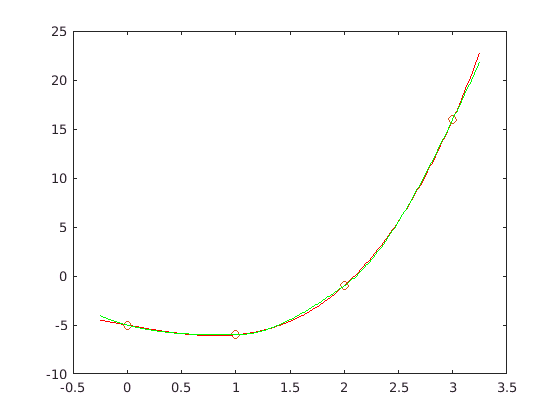

hold on
plot(x, y, 'o', u, v1, '-')
plot(u, v2, 'r')
plot(u, v3, 'g')
hold off


sym_x=sym('x')

$$sym\_x = x$$

p1= lagrange_polyinterp1(x,y,sym_x)

$$p1 = \frac{8\,x\,\left(x-1\right)\,\left(x-2\right)}{3}+\frac{x\,\left(x-1\right)\,\left(x-3\right)}{2}-3\,x\,\left(x-2\right)\,\left(x-3\right)+\frac{5\,\left(x-1\right)\,\left(x-2\right)\,\left(x-3\right)}{6}$$


simplify(p1)

$$ans = x^{3}-2\,x-5$$

function v = lagrange_polyinterp1(x,f,u)
    n=length(x);
    m=length(u);
    v=zeros(m,1);
    
    for k=1:m
        sum_val=0;
        for j=1:n
            prod=1;
            for i=1:n
                if i~=j
                    prod=prod* (u(k)-x(i)) / (x(j)-x(i));
                end
            end
            sum_val=sum_val+prod*f(j);
        end
        if isa(u, 'sym')
            v=sum_val;
        else
            v(k)=sum_val;
        end
    end 
end